# Collision avoidance simulink model

This code shows how to setup a simulink model for distributed collision avoidance. Including description of the underlying ADMM (Alternating Direction Method of Multipliers) algorithm.

## Model Overview

We will begin by exploring the simulink model, looking at the connectivity and layout of the various subsystems used in the simulation.

### Open the Model

Firstly, clear the workspace and add functions to the current path, then open up the chosen simulink model. There are 2 slightly different models but both have the same main steps, triggered subsystem simply allows for triggering the path planning according to pulses.

clear
addpath("Funz");
mode = "Triggered_subsystem_mdl";
open_system(mode);

Program interruption has been detected.

### Inputs & outputs

The planning and simulation subsystem takes in 3 inputs: A connectivity graph (or a set of connectivity graphs for varying communication), an initial state vector  (x0) and a reference/ goal state (r).

The initial and reference states should be input as matrices with each row being a 1x6 row vector containing the relevant state. This vector contains the XYZ position and their derivatives in a North-East-Up coordinate frame.

In addition to these inputs we also need to specify a few further parameters. These are the number of steps to look ahead during the path planning (N), the minimum separation between drones (delta), the maximum acceleration of a drone in any direction (note this script allows a drone to accelerate maximally in all 3 directions at once), the simulation run time, the time period between updates to the path planning and the discretisation timestep used in the path planning. 

These can be setup as follows (or a premade scenario can be selected).

option = "custom";
if option ~="custom"
    addpath("Scenarios");
    load(option);
else
    N =30 ;%number of steps to look ahead
    delta = 0.4; %collision avoidance separation
    max_acc = 1; %max drone acceleration
    endTime = 10; %simulation run time
    MPC_period = 1; %seconds between each trajectory update
    
    T = 0.1; %discretisation time step
    
    r = [
         1.0,1.4,0.0, 0,0,0;
         0.6,0.4,0.0, 0,0,0;
         0.0,0.9,0.0, 0,0,0;
         0.0,0.0,1.0, 0,0,0;
         0.0,0.0,0.0, 0,0,0;
         ];
    
    x0 = [
          0.0,0.5,0.0, 0,0,0;
          0.2,0.9,0.0, 0,0,0;
          1.0,0.3,0.0, 0,0,0;
          0.0,0.0,0.0, 0,0,0;
          0.0,0.0,1.0, 0,0,0;
          ];
    
    M = size(x0,1); % Number of agents (derived from number of rows of x0)
    
    graph_form{1} = ones(M) - eye(M); %connectivity graph
    % graph_form{1} = [0 1 0 0; 1 0 0 0; 0 0 0 1; 0 0 1 0]; %define connection graphs
    % graph_form{2} = [0 0 1 0; 0 0 0 1; 1 0 0 0; 0 1 0 0];
    % graph_form{3} = [0 0 0 1; 0 0 1 0; 0 1 0 0; 1 0 0 0];
    
    graph_update_step = 1; %how many MPC calls before connection graph is updated
    
    %puts graphs into a 3D matrix to allow proper iteration
    if size(graph_form,2) == 1
        graph_form{2} = graph_form{1};
    end
    
    
    for i = 1:size(graph_form,2)
        graph(:,:,graph_update_step*(i-1)+1:i*graph_update_step) = graph_form{i};
    end
end

Upon completion the subsystem outputs the positions of the drones sampled at the chosen time step (T).

### Model Architecture

Opening this provides some insight into the separate planning and simulation steps.

open_system(mode + '/Planning and simulation');

The path planning block takes the current states in as the initial states for the current iteration, as well as the fixed reference states and the current connectivity graph. This block then loops over a number of iterations of the ADMM algorithm (which will be explored later) and outputs accelerations for the next *N* time steps.

These accelerations are then fed into a Simulation subsystem. The resulting state is then sent back to the path planning block.

### Simulation Subsystem

open_system(mode + '/Planning and simulation/Simulate');

In this subsytem we find the current acceleration command (found by taking the *k*th acceleration vector from the most recent path planning output) and then convert this from a simple 3D acceleration to pitch, roll, thrust commands for the UAV guidance model (since this provides us with 3 DoF we simply set yaw rate to 0, but do still use it when calculating commands in case of any drift).

These commands are then fed into a control bus which is fed into the [UAV guidance block](https://uk.mathworks.com/help/uav/ref/guidancemodel.html). The UAV states are then updated and outputted, with the yaw being fed back around.

The UAV guidance block outputs a 13D state vector which includes euler angles and thrust. For our path planning subsystem we only require positions and velocities, and so the change coord frame selects these and converts them from a North-East-Down coordinate frame to a North-East-Up coordinate frame with a global origin.

### Path Planning Subsystem

if mode == "Triggered_subsystem_mdl"
    path = mode + '/Planning and simulation/Path Planning/For loop';
else
    path = mode + '/Planning and simulation/Path Planning';
end
open_system(path);

The final subsystem to explore is the path planning subsystem, in this subsystem the UAVs use the ADMM algorithm to plan a feasile trajectory $w$. They then calculate the acceleration at each time step as follows:

$a\left(k\right)=\frac{w\left(k+2\right)-2\;w\left(k+1\right)+w\left(k\right)}{T^2 }$,

and output this information for the simulation step.

In this subsystem each block is a step of the ADMM algorithm, with the exception of x_bar setup which runs only on the first iteration to set up initial trajectories. 

## ADMM Algorithm

We now move on to explore the ADMM algorithm, with an explanation of each step of the algorithm and follow a single iteration.

### Parameters

In order to run the ADMM algorithm we first need to define  a few key parameters. We start with the model definition, in order to simplify the optimisation we have chosen a very simple double integrator model with updates of the form:


$$\begin{array}{l}
p\left(k+1\right)=p\left(k\right)+T\;v\left(k\right)\\
v\left(k+1\right)=v\left(k\right)+T\;a\left(k\right)
\end{array}$$


p,v and a being position, velocity and acceleration respectively, with acceleration being the chosen control input.

We also define the number of states (6), number of inputs (3 for acceleration in each direction) and finally the number of dimensions.

Finally, we have the objective matrices, which are defined as in LQR control. These can be adjusted for differing performance depending on specific requirements.


A = [1 0 0 T 0 0;
    0 1 0 0 T 0;
    0 0 1 0 0 T;
    0 0 0 1 0 0;
    0 0 0 0 1 0;
    0 0 0 0 0 1];

B = [0 0 0;
    0 0 0;
    0 0 0;
    T 0 0;
    0 T 0;
    0 0 T];

m = 0.1; %Mass

%set up model structure
model.A = A;
model.B = B;
model.umax = max_acc;
model.umin = -max_acc;

nx = size(model.A,1); %state vector dimension
nu = size(model.B,2); %number of inputs
Nd = 3; %number of dimensions

%Objective matrices setup (note that we ignore velocity in the
%optimisation)
PosQ = eye(Nd)*10;
velQ = eye(nx-Nd)*0; 
Objective.Q = blkdiag(PosQ,velQ);
Objective.R = eye(nu)*13;
Objective.N = N;

Acc_from_pos = eye((N+1)*Nd) + ...
               [zeros((N)*Nd,Nd) -2*eye(N*Nd); zeros(Nd,(N+1)*Nd)] + ...
               [zeros((N-1)*Nd,2*Nd) eye((N-1)*Nd); zeros(2*Nd,(N+1)*Nd)];
Acc_from_pos = Acc_from_pos/T^2; %finds accelerations based on only position
Bus_setup; %sets up buses for model

### Initial Trajectory

In order to start the optimisation we need some initial trajectory to optimise around, for this we simply take an optimal trajectory which does not account for collision avoidance as follows:

x_init = zeros(nx*(N+1),M);
u_init = zeros(nu*N,M);
for i = 1:M
    [x_init(:,i),u_init(:,i)] = init_traj(ADMM_vec(i).rho,Objective,constraints_struct(i),model); %initial solution
end

Init_traj which simply minimises $\sum_0^N x^T Q\;x+u^T R\;u$ whilst ensuring the planned trajectory is feasible (i.e. is possible according to the simple quadrotor models employed and does not exceed the maximum acceleration).

We then communicate these initial trajectories to all neighbours (i.e. drones that we can communicate with).

for i =1:M
    ADMM_vec(i).x = x_init(:,i);
    ADMM_vec(i).u = u_init(:,i);
    ADMM_vec(i).x_bar(:,i) = x_init(:,i);
    nonzero_N_j = nonzeros(constraints_struct(i).N_j);
    for j = 1:nnz(constraints_struct(i).N_j)
        ADMM_vec(i).x_bar(:,nonzero_N_j(j)) = x_init(:,nonzero_N_j(j));
    end
end

Following this all drones have an initial trajectory for all their neighbours and can then begin the main steps of the algorithm.

### Predict

This initial step is parallelisable, and we use a for each susbsytem to make use of this. Agents try to minimise the actual cost function (in the first term). The other terms are the augmented lagrangian terms, with the first 2 encompassing the constraint $p_i =w_i$. The final component involves the agent trying to stay close to the trajectory proposed by all its neighnours. The constraints in this step ensure the trajectory follows the agent dynamics (the double integrator model).

This can be recast into a form recognisable to quadprog and the update step is run as follows:

for i = 1:M
    admmxlength = nx*(N+1);
    admmulength = nu*(N);
    umin = -max_acc;
    umax = max_acc;
    min_input = repmat(ones(nu,1)*umin,N,1);
    max_input = repmat(ones(nu,1)*umax,N,1);
    
    u_bound = [inf((N+1)*nx,1);max_input];
    l_bound = [-inf((N+1)*nx,1);min_input];
    
    
    posM = blkdiag(eye(Nd),zeros(nx-Nd)); % Matrix to take only position from the state vector x (zeros rest)
    d = [eye(Nd),zeros(Nd,nx-Nd)]; % Matrix to take only position from the state vector x (only returns pos)
    posMN = kron(eye(N+1),d); %returns pos across time steps
    
    Ax = kron(speye(N+1), -speye(nx)) + kron(sparse(diag(ones(N, 1), -1)), A);
    Bu = kron([sparse(1, N); speye(N)], B);
    Aeq = [Ax, Bu];
    b_eq = [-constraints_struct(i).x0 zeros(1, N*nx)]';
    Q = Objective.Q;
    R = Objective.R
    P_new = blkdiag( kron(eye(N), Q+ (nnz(constraints_struct(i).N_j)+1)*ADMM_vec(i).rho/2*posM ), ...
        Q+(nnz(constraints_struct(i).N_j)+1)*ADMM_vec(i).rho/2*posM, kron(eye(N), R) );

    q = prediction_linear(ADMM_vec(i).lambda, ...
        ADMM_vec(i).lambda_from_j, ...
        ADMM_vec(i).w, ...
        ADMM_vec(i).w_from_j, ...
        ADMM_vec(i).rho, ...
        constraints_struct(i).r', Q, N, nu, posMN,nonzeros(constraints_struct(i).N_j));

    init = [ADMM_vec(i).x; ADMM_vec(i).u];
    opts = optimoptions('quadprog','Display','off','Algorithm','Active-set');
    res = quadprog(P_new,q,[],[], full(Aeq), b_eq, l_bound, u_bound,init,opts);

    ADMM_vec(i).x = res(1:admmxlength);
    ADMM_vec(i).u = res(admmxlength+1 : admmxlength + admmulength);
end

R =     13     0     0
     0    13     0
     0     0    13


R =     13     0     0
     0    13     0
     0     0    13


R =     13     0     0
     0    13     0
     0     0    13


R =     13     0     0
     0    13     0
     0     0    13


R =     13     0     0
     0    13     0
     0     0    13


### Communicate

Following the prediction step all agents share their proposed trajectories $p_i$ to all their neighbours so that these can then be used to plan collision free trajectories in the coordinate step. Agents then store these as x_bar.

for i =1:M
    ADMM_vec(i).x_bar(:,i) = ADMM_vec(i).x;
    nonzero_N_j = nonzeros(constraints_struct(i).N_j);
    for j = 1:nnz(constraints_struct(i).N_j)
        ADMM_vec(i).x_bar(:,nonzero_N_j(j)) = ADMM_vec(nonzero_N_j(j)).x;
    end
end

### Coordinate

Again, this step is parallelisable and we therefore use a foreach subsystem. Each agent minimises the augmented lagrangian with respect to the z variables ($w_i$ and $w_{i\to j}$ here) and the collision avoidance constrain is enforced, we use the most recent known trajectories for all neighbours for this.

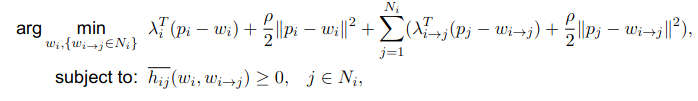

The code for this is as follows:

for i = 1:M
    H = kron(eye(N+1),repmat(d, nnz(constraints_struct(i).N_j), 1));
    Hw = kron(eye(N+1),repmat(eye(nu), nnz(constraints_struct(i).N_j), 1));
    for j = 1:nnz(constraints_struct(i).N_j)
        v = zeros(nnz(constraints_struct(i).N_j),1);
        v(j) = 1;
        H_M = kron(eye(N+1),kron(v, -1*d));
        H_Mw = kron(eye(N+1),kron(v, -1*eye(nu)));
        
        H =  [H, H_M];
        Hw = [Hw,H_Mw];
    end
    rhoM = kron(speye((N+1)),ADMM_vec(i).rho/2*eye(nu)); % matrix for the quadratic objective formualation
    Pc = kron(eye(1+nnz(constraints_struct(i).N_j)),rhoM);


    qc = coordination_linear(ADMM_vec(i).lambda,ADMM_vec(i).lambda_to_j,ADMM_vec(i).rho, ...
        ADMM_vec(i).x_bar,posMN,constraints_struct(i).N_j,i);

    % Update matrices
    actual_N_j = nonzeros(constraints_struct(i).N_j);

    init = ADMM_vec(i).w;
    for j = 1:nnz(constraints_struct(i).N_j)
        init = [init;ADMM_vec(i).w_to_j(:,actual_N_j(j))];
    end
    [A_ineq,l_ineq] = communicate(ADMM_vec(i).x_bar,N,constraints_struct(i).N_j,H,Hw,constraints_struct(i).delta,nu,i);

    if A_ineq*init < l_ineq
        init = A_ineq\l_ineq;
    end
    opts = optimoptions('quadprog','Display','off','Algorithm','Active-set');
    resc = quadprog(full(Pc),qc,-A_ineq,-l_ineq,[],[],[],[],init,opts);
    %             resc = qp_grad(full(Pc),qc,-A_ineq,-l_ineq,[],[],[],[],init,1e-2);


    ADMM_vec(i).w = resc(1:Nd*(N+1),1);
    for j = 1:nnz(constraints_struct(i).N_j)
        ADMM_vec(i).w_to_j(:,actual_N_j(j)) = resc(j*obj.Nd*(obj.N+1)+1:(j+1)*obj.Nd*(obj.N+1),1);
    end
end

### Mediate

Next, the dual variables (lambda) are all updated.

for i =1:M
    ADMM_vec(i).lambda = ADMM_vec(i).lambda + ADMM_vec(i).rho * (posMN * ADMM_vec(i).x-ADMM_vec(i).w);
    nonzero_N_j = nonzeros(constraints_struct(i).N_j);
    for j = 1:nnz(constraints_struct(i).N_j)
        ADMM_vec(i).lambda_to_j(:,nonzero_N_j(j)) = ADMM_vec(i).lambda_to_j(:,nonzero_N_j(j)) +...
        ADMM_vec(i).rho * (posMN*ADMM_vec(i).x_bar(:,nonzero_N_j(j)) - ADMM_vec(i).w_to_j(:,nonzero_N_j(j)));
    end
end

### Final Communication

Finally, each agent communicates its proposed trajectories witoj and dual variables lambdaitoj to all its neighbours and receives these variables from its neighbours.

for i = 1:M
    nonzero_N_j = nonzeros(constraints_struct(i).N_j);
    for j = 1:nnz(constraints_struct(i).N_j)
        curr_comm = nonzero_N_j(j);
        ADMM_vec(i).lambda_from_j(:,nonzero_N_j(j)) = ADMM_vec(curr_comm).lambda_to_j(:,i);
        ADMM_vec(i).w_from_j(:,nonzero_N_j(j)) = ADMM_vec(curr_comm).w_to_j(:,i);
    end
end

We would then return to the prediction step and continue to iterate for a fixed number of iterations.

## Run Whole Simulation

We can now return to the simulink model which contains all these steps and runs them a fixed number of times for us.

w=warning('off','all');
tic
simout = sim(mode,'StopTime', string(endTime));
sim_time = toc

## View results

Finally, we can observe the results to see the final paths taken by the drones. In this step we also print out the final minimum separation between any 2 drones.

The initial positions of the drones are shown with circles, their goals are shown with crosses, and any points at which drones have been closer than the minimum specified by delta are shown with a red diamond.

x = reshape(simout.yout{1}.Values.Data(:,:,:),M,[])';
visualise_drones_3d(r,x,T,nx,delta);